# Filtracja obrazu

% data loader 
lena512 = imread('lena512.png');

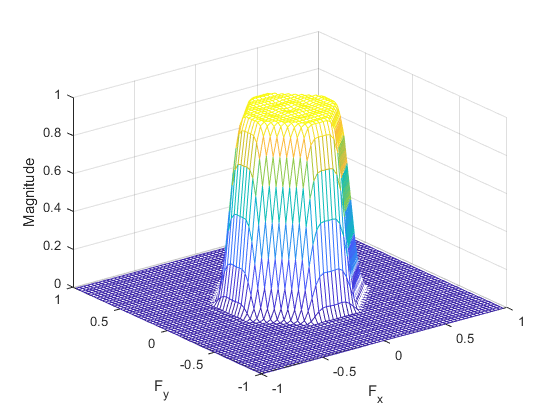

% lowpass
[f1,f2] = freqspace(32,'meshgrid');
win = 0.54 - 0.46*cos(2*pi*(0:31)/31);
r = sqrt(f1.^2 + f2.^2);
Hd = ones(32); 
Hd(r>0.4) = 0;

H_lowpass = fwind1(Hd,hamming(32));
freqz2(H_lowpass)

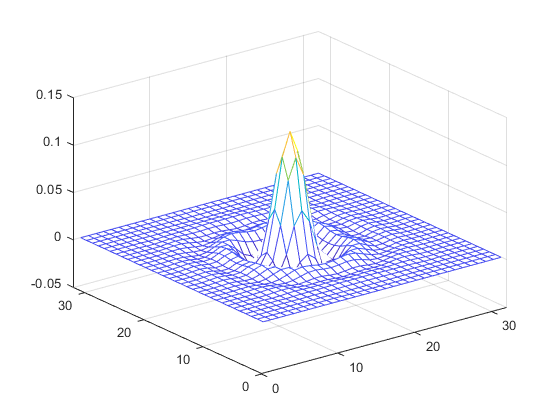

figure; mesh(H_lowpass)

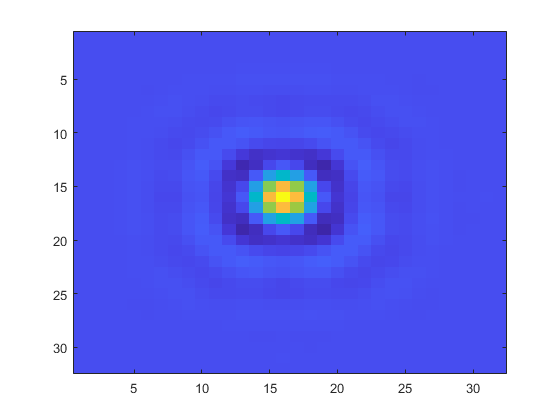

figure; imagesc(H_lowpass)

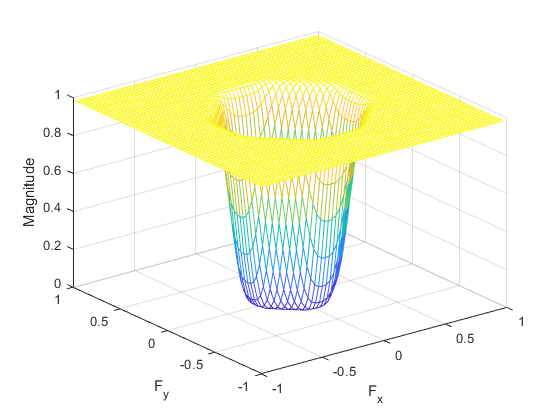

% highpass
Hd2 = ones(32) - abs(Hd); 
H_highpass = fwind1(Hd2,blackman(32));

figure; freqz2(H_highpass)

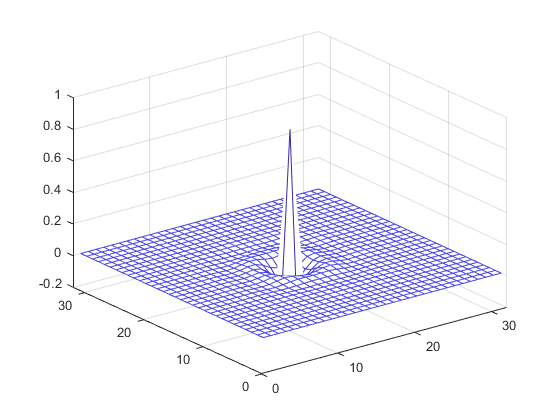

figure; mesh(H_highpass)

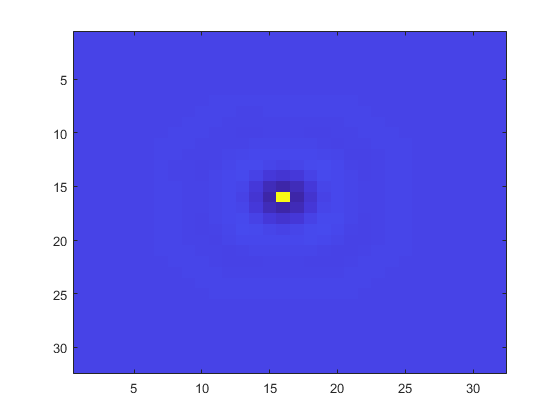

figure; imagesc(H_highpass)

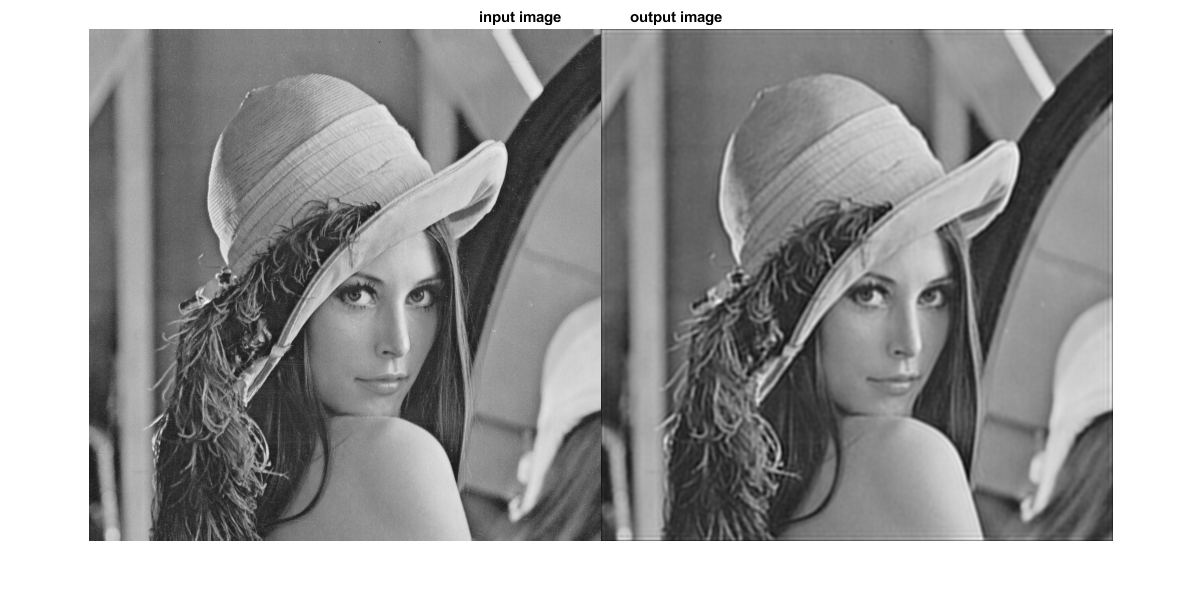

lena512_fil = filter2(H_lowpass, lena512);

figure;
imshow([lena512 lena512_fil]);title('input image                 output image');

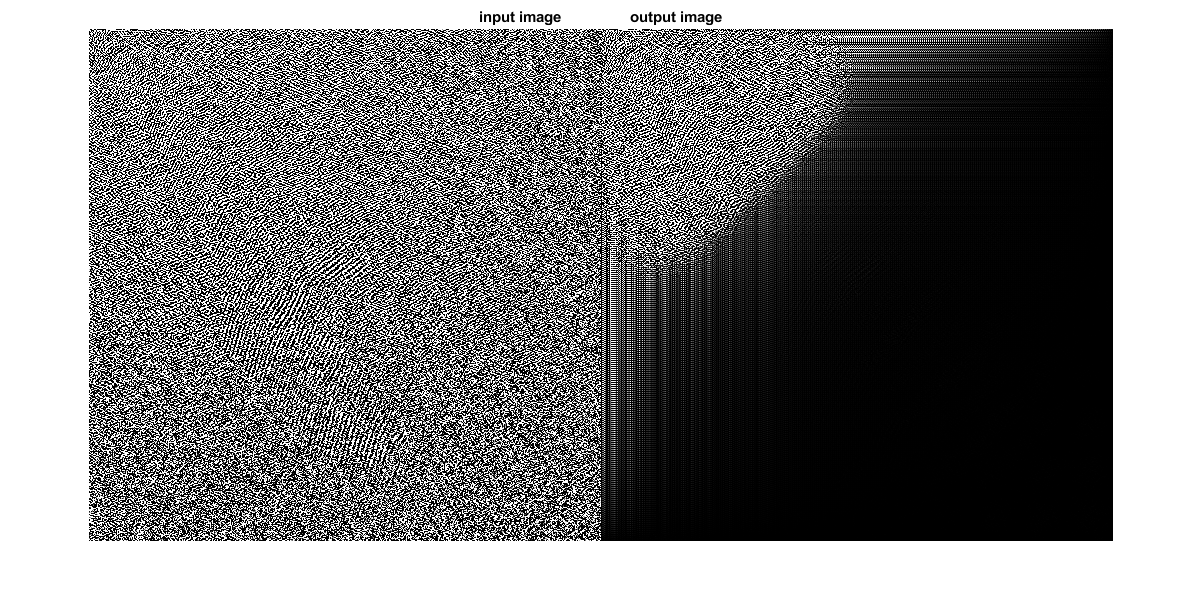


% spectrum 
figure;
imshow([dct2(lena512) dct2(lena512_fil)]);title('input image                 output image');

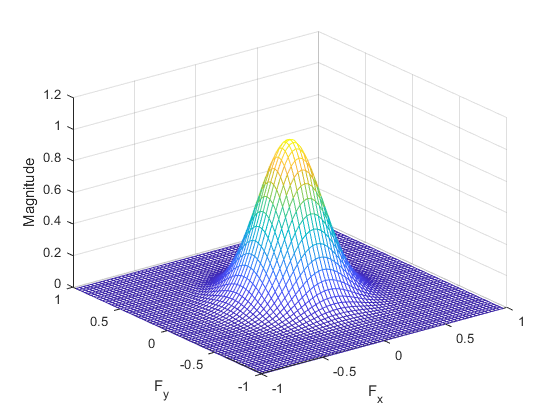

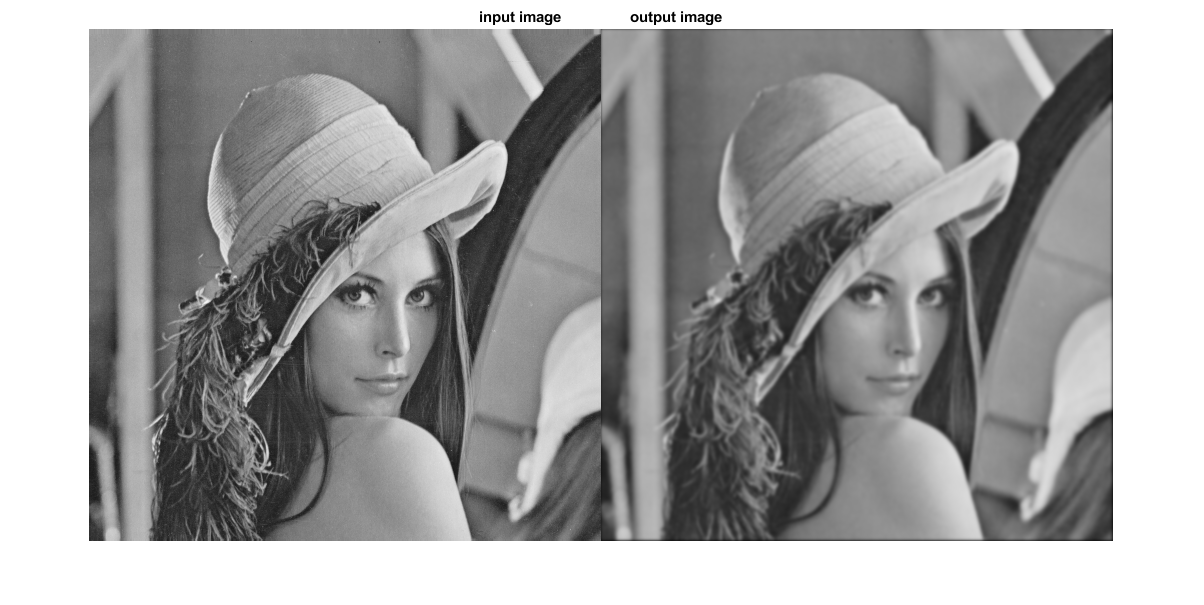

% Gaussian lowpass filter. Not recommended. Use imgaussfilt or imgaussfilt3 instead.
H_gauss = fspecial('gaussian',32,1.5);
lena_gauss = filter2(H_gauss,lena512);

figure; freqz2(H_gauss)
figure; mesh(H_gauss)
figure; imagesc(H_gauss)

figure
imshow([lena512 lena_gauss]);title('input image                 output image');

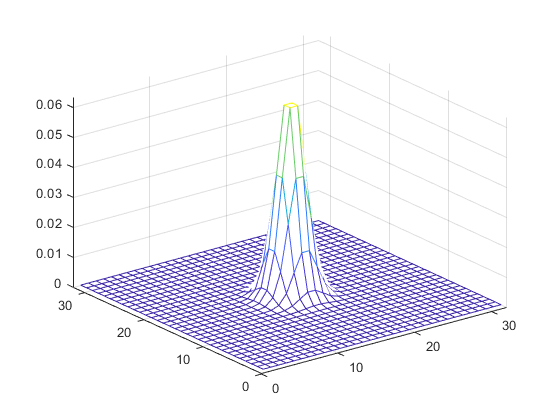

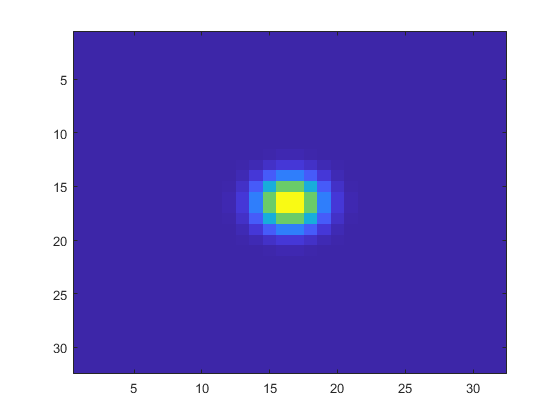

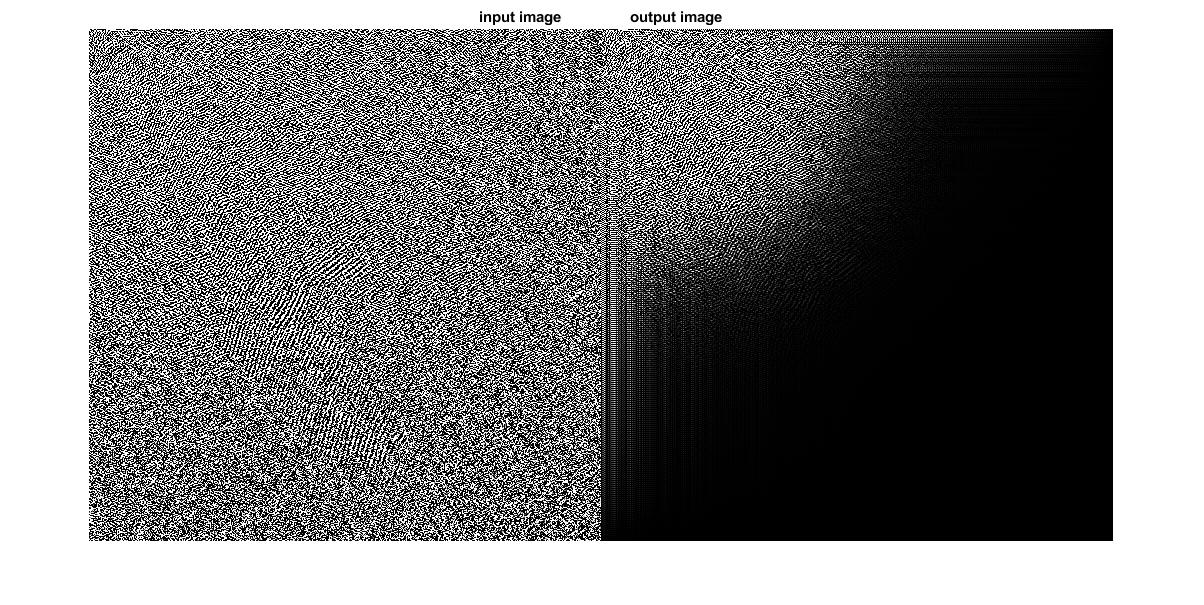


figure 
imshow([dct2(lena512) dct2(lena_gauss)]);title('input image                 output image');